oclear 
close all
clc

**Model definition and data generation**

Given dataset y = a0+b0*x+e

% True value of the parameters:
a_true = -2.923;
b_true = 7.18;

Number of data to generate:

N=100;

Input:

x= 0;

Noise:

noise_std = 3.8;
eG  = noise_std*randn(N,1);

Output:

y = b_true*x;

Noise corrupted output:

yn= y + eG;

**Identification using Least sqaures**

Matrix H:

H = zeros(N,2);
for i=1:N
    H(i,:) = [1 x];
end

Calcualtion of theta matrix:

th = (H'*H)\H'*yn;

ahat = th(1)

ahat = -0.2460

bhat = th(2)

bhat = NaN

Prediction of y

ypred = zeros(N,1);
for i=1:N
   ypred(i) = ahat + bhat*x;
end

Compare with real data and compute RMS error

predERROR = yn-ypred;
predRMSE  = rms(predERROR);
disp(['Prediction RMS error is: ' num2str(predRMSE)])

Prediction RMS error is: NaN


Plot

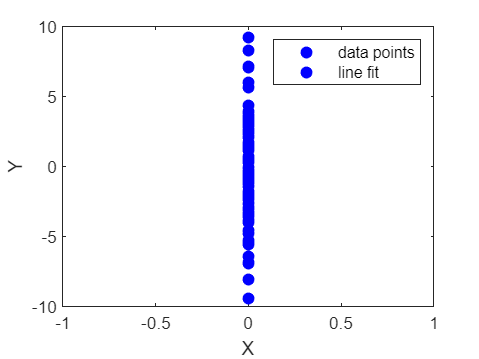

plot(x,yn,'bo',...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0,0,1])
hold on
plot(x,ypred,'-m')
legend('data points','line fit')
xlabel('X')
ylabel('Y')